# Emulate Measured Current Input, using ADC component

To emulate the value of the Current consumed by the Motor, we can use a potentiometer, and virtually apply the voltage over a RShunt resistor. Unfortunately, the **S32K396-BGA-DC1** is not equipped with an onboard potentiometer but, due to the multitude of pins available on the board, we can connect an external potentiometer.

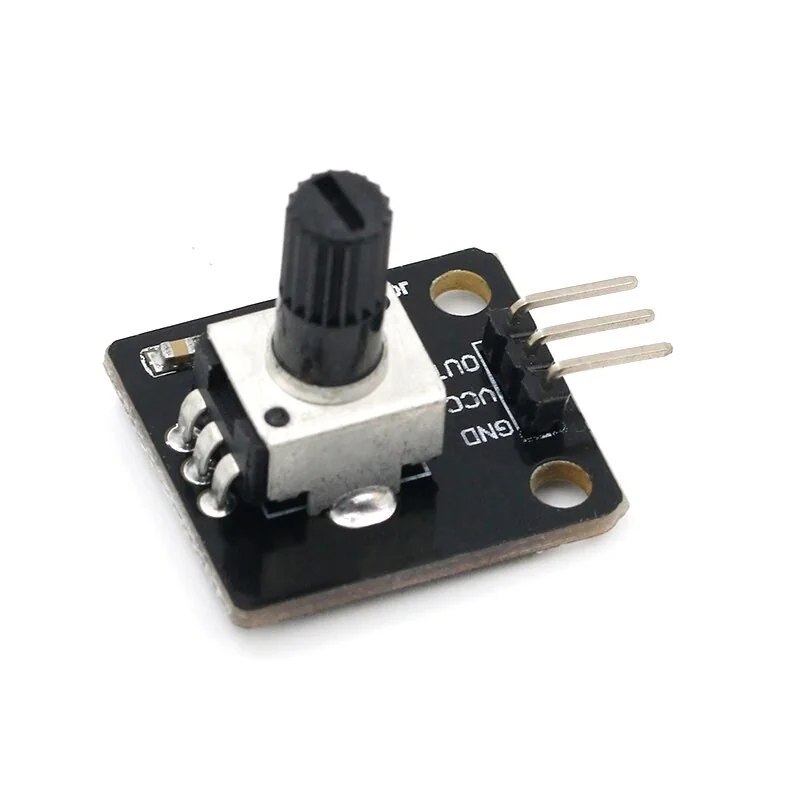

Rotating the potentiometer will result in modifying the value of the current consumed by the motor, and can act as the input for the **FaultLogic** system. The measured **ADC** **Raw** value will be converted to **Volts**, using the **Raw2Volts** subsystem, and knowing the **RShunt** value, we can translate that into **Amperes **applying** Ohm's Law. **This is already implemented in the Simulink model, using the following equations:

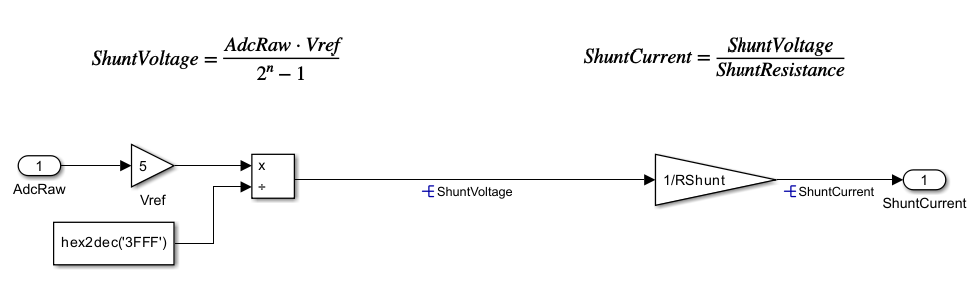

For our convenience, we can use the J39 and J62 headers to connect the potentiometer as follows:

- **Potentiometer.VCC - J39.1 **

- **Potentiometer.GND - J39.4**

- **Potentiometer.OUT - J62.32 [PTD27]**

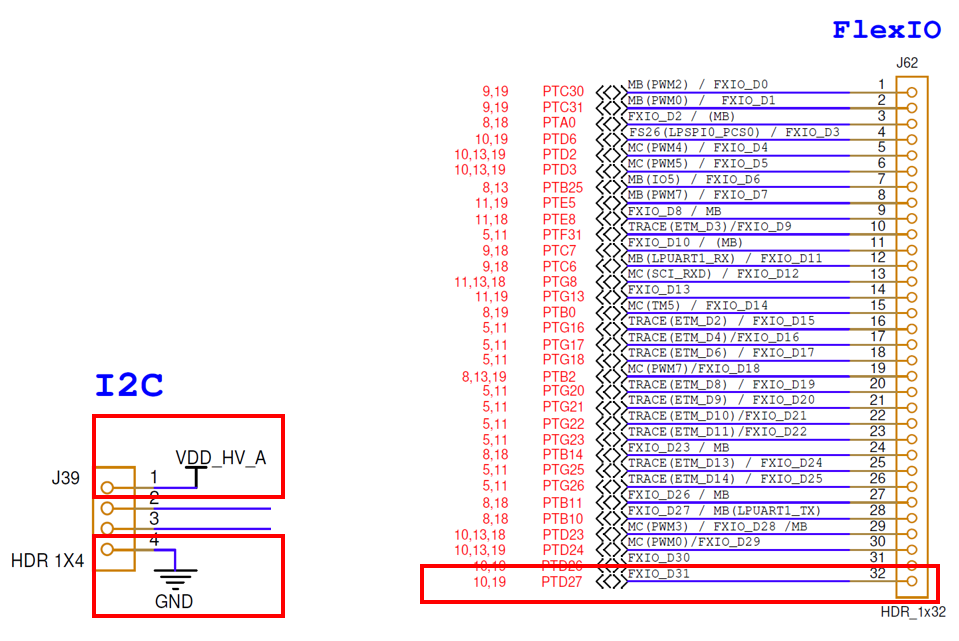

For an analog functionality in the MCU schematic, we can notice that the **PTD27** can be muxed internally to the **ADC4_P6 or** **ADC5_P2 **(the one we will use today).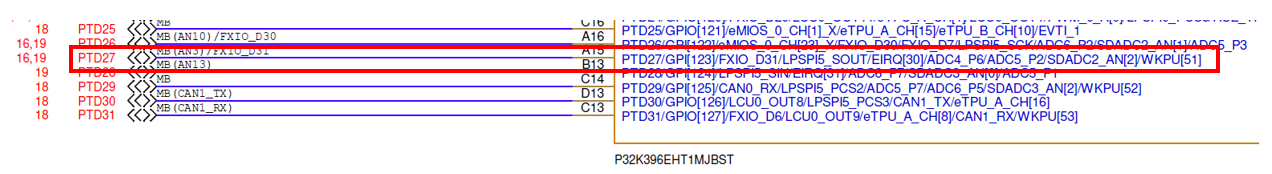

The S32K3 ADC module, alongside **PTD27** pins, **ADC clock** and **ADC peripheral** needs to be configured using the external configuration tool. MBDT for S32K3 is compatible with both **EB Tresos** and NXP's **S32 Configuration Tools**. S32CT is integrated and delivered together with the **MBDT for S32K3** and this is the one we will be using for today's class. More details in the next exercise.

ADC peripheral is configured to work in **Interrupt** mode. The interrupt will be triggered after the conversion is completed and the **end of conversion **flagged raised.

This exercise's purpose is to read the ADC conversion result buffer inside the **Interrupt Service Routine**.

All the ADC peripheral configuration has been set using the **S32 Configuration Tools **and it is currently stored inside the **S32K39_CodeGenConfig.mex** file associated with the model.

### Configure ADC Notification Callback

- Go to **SIMULATION** tab and click on **Library Browser**.

- Expand the **NXP Model-Based Design Toolbox for S32K3xx MCUs -> S32K3xx Core, System, Peripherals and Utilities/ISR Blocks.** 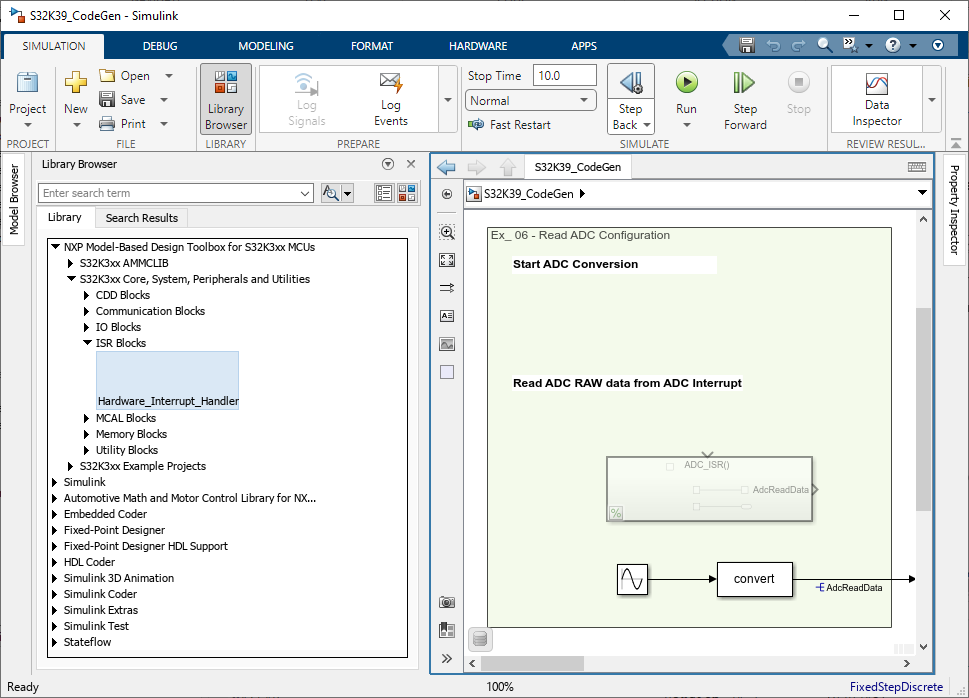                                     

- Drag & drop the** Hardware_Interrupt_Handler **block into the model, inside the Green area.

- Connect ** Hardware_Interrupt_Handler **block output to the** ADC_ISR** Function-Call Subsystem. Uncomment this subsystem block first.

- Double click on the block and for the **Interrupt group** drop-down select **Adc,** and from the **Interrupt Handler** drop-down select the **Adc_Adc5Group0Notification** callback.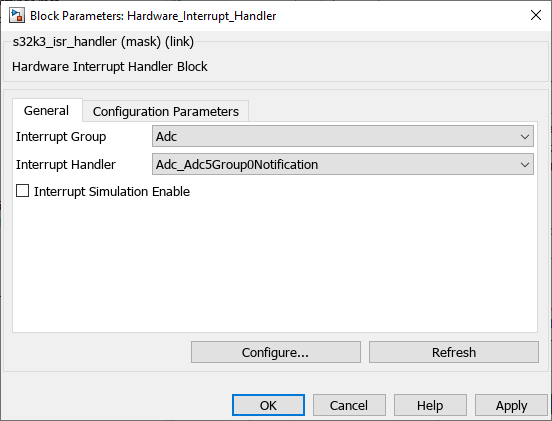

- The callback function prototype for the **ADC_ISR** has been configured.

###  ADC Data Acquisition

- Inside the** ADC_ISR** Function-Call subsystem, drag & drop an** Adc** block from **IO Blocks **Library.

- Double click on **Adc** block, and from the **Function** drop-down select the **Adc_ReadGroup** function. This block inserts into the generated code the function that reads the ADC conversion group results. This function will be executed inside the interrupt callback, asynchronously with the model execution step timing. The second parameter of this function specifies the channel group conversion, which is initialized in the configuration file attached to the model. This conversion group contains a single **ADC5 P2** channel mapped to **PTD27** pin, connected to the potentiometer from the EVB.                      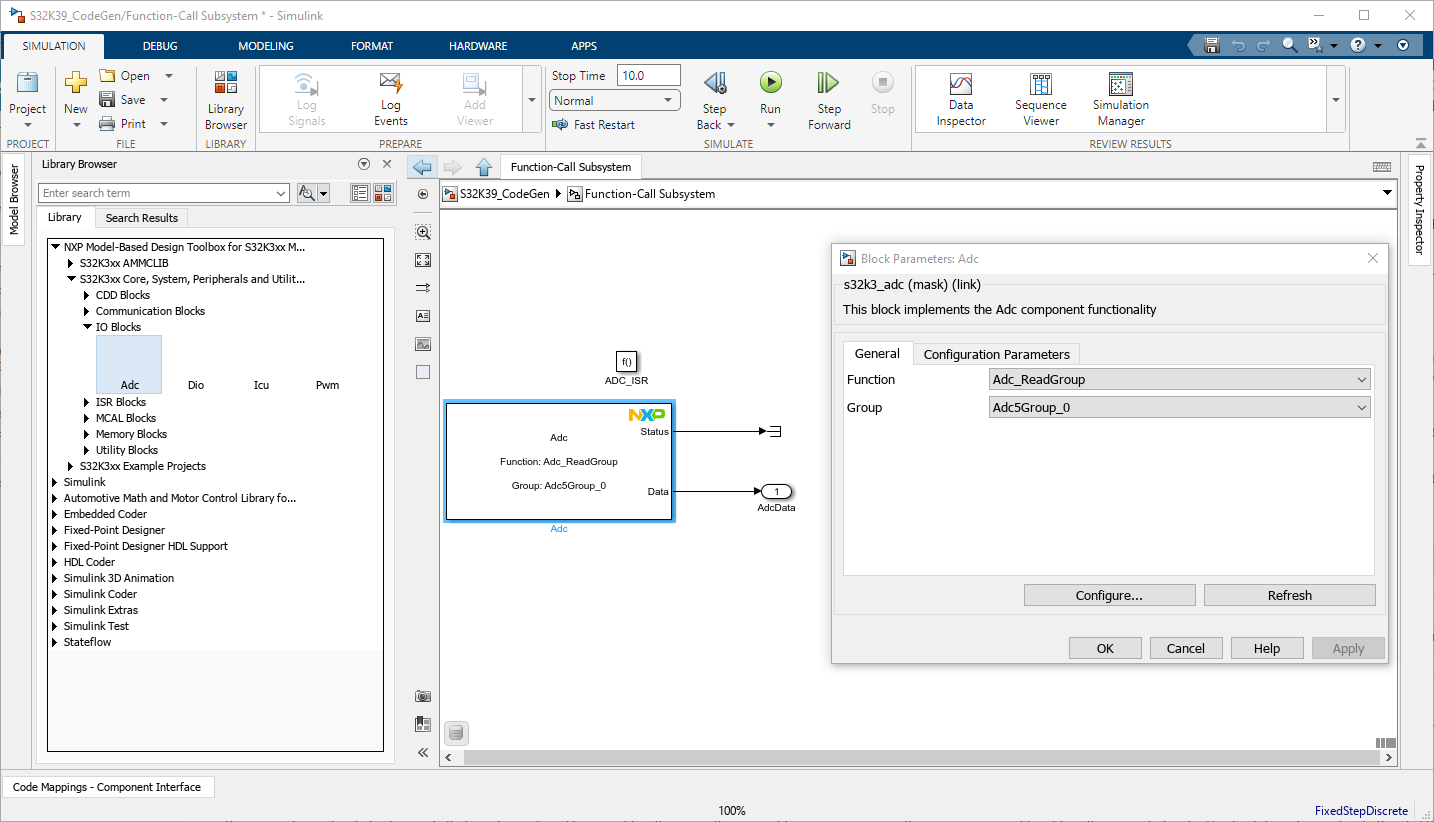

- Back in the main model, delete the Sine Wave generation block and connect the AdcReadData to the output of the block. 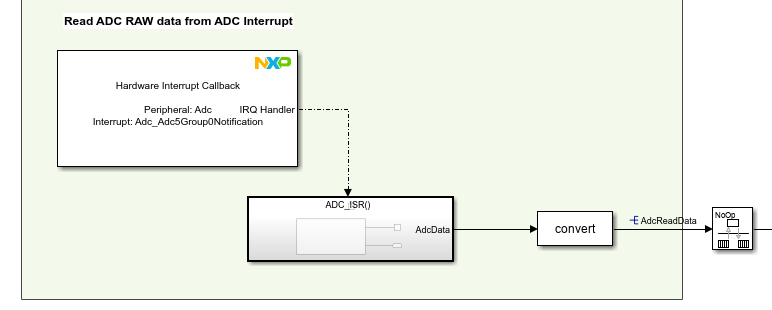

### Start ADC Conversion

Go back to the main model.

Starting the ADC conversion at each model execution step is achieved by calling the **Adc_StartGroupConversion** function.

- Drag & drop an **Adc** Simulink block.

- Select from the function drop-down **Adc_StartGroupConversion.**

                 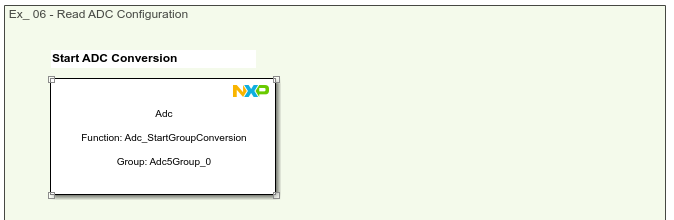

### Enable ADC Notification

At this point, we have completed the **ADC Start Conversion** and the **ADC Conversion Read **actions, and we are almost ready with our implementation. Still, the** End of Conversion** notification source needs to be enabled.

To enable the notification mechanism for the requested ADC channel group, the **Adc_EnableGroupNotification **function needs to be called before the model step execution. 

To achieve this functionality, we use **Initialize **Simulink subsystem. This subsystem helps us to generate code, which will be executed only once, during initialization sequence.

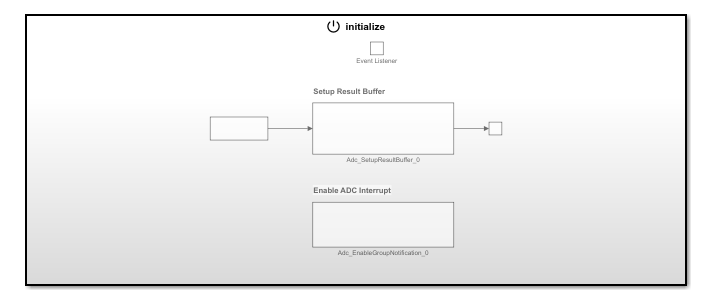

To enable notification, inside the Initalize subsystem, an **ADC** block has been added, the **Adc_EnableGroupNotification** has been selected, for the **Adc5Group_0**.

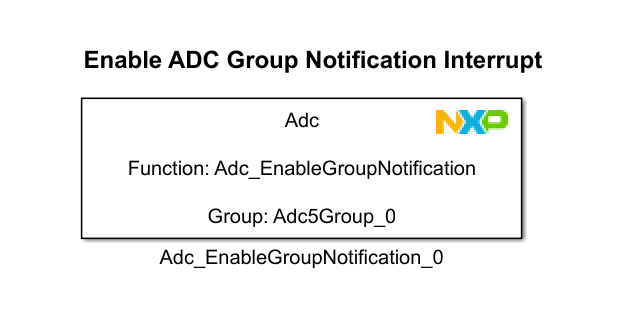

### Initialize Conversion Result Buffer

To add a memory location where ADC to be able to deliver the ADC converted values, the result conversion buffer needs to be initialized. This configuration needs to be performed only once, before model execution step.

Again, in the Initialize Block, an ADC block has been inserted and the **Adc_SetupResultBuffer** has been selected for the **Adc5Group_0** notification.

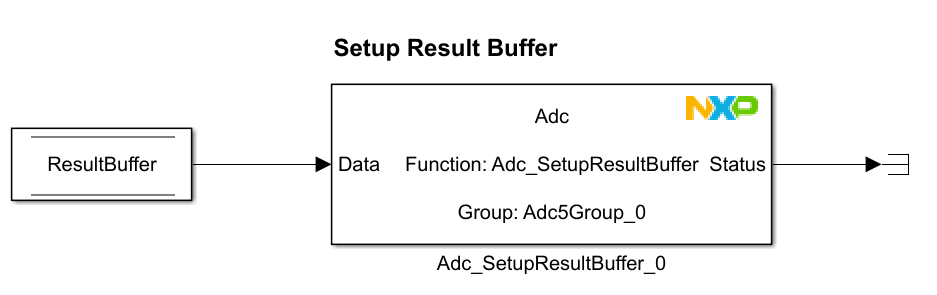

**Deploy the Adc changes on the target**

After the ADC blocks are configured, deploy the code to the target. The shortcut **Ctrl+B** can be used for this action.

Once deployed, open the FreeMASTER and use the potentiometer to change the ShuntCurrent and observe the analog value for the measured current.

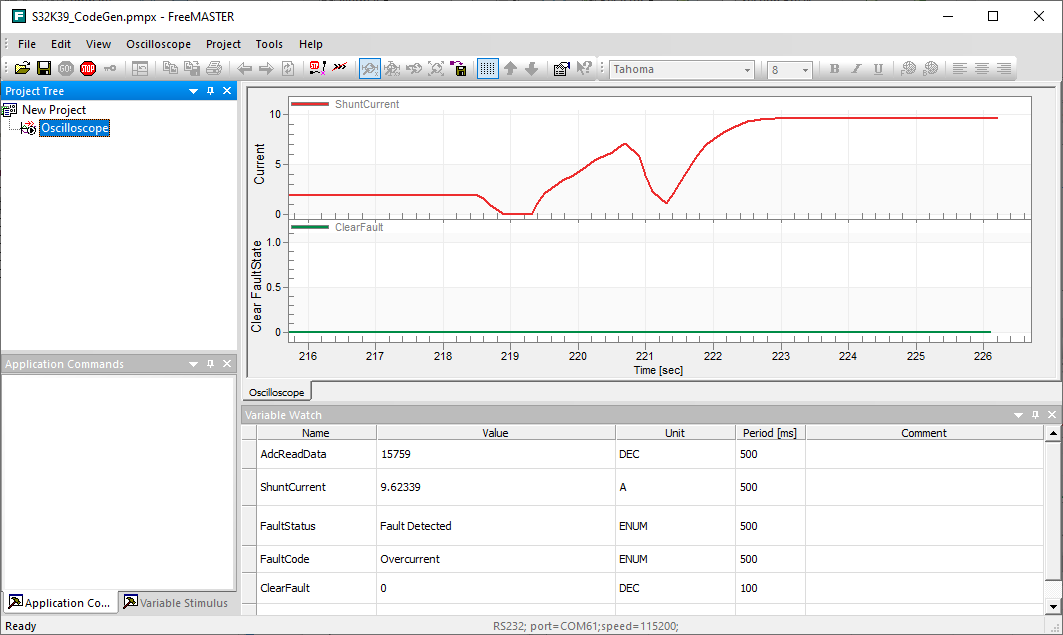

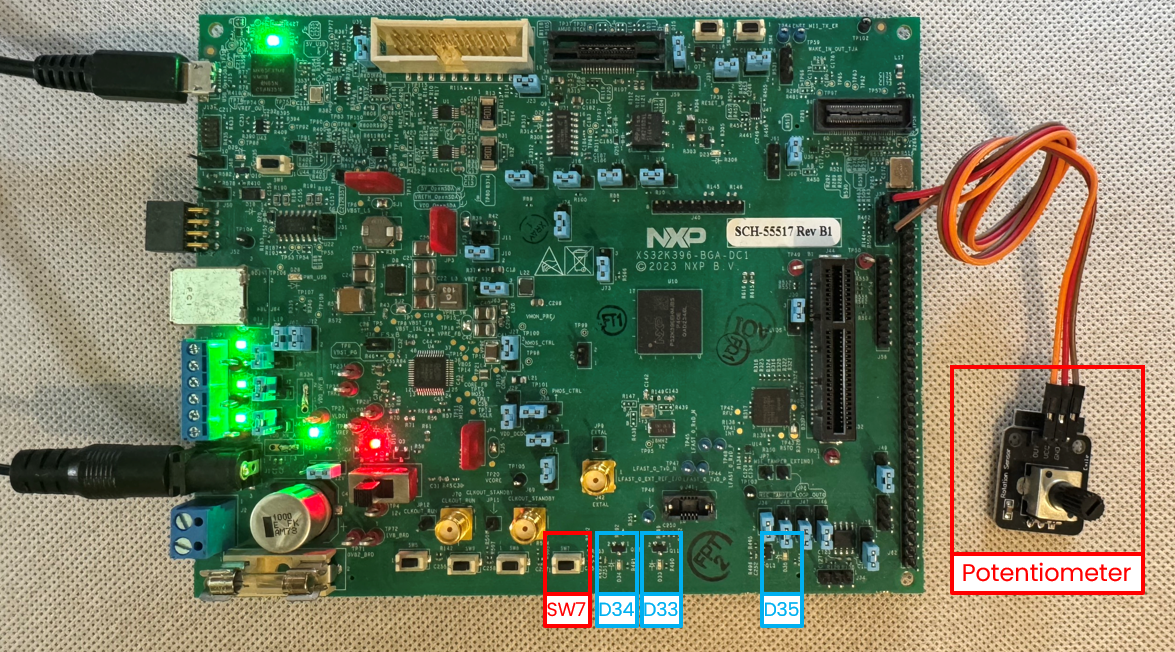

In the next exercise we will use the DIO blocks to show the status on the board and to reset the state. Open the next exercises.

edit('Ex_07');